# 刚性问题

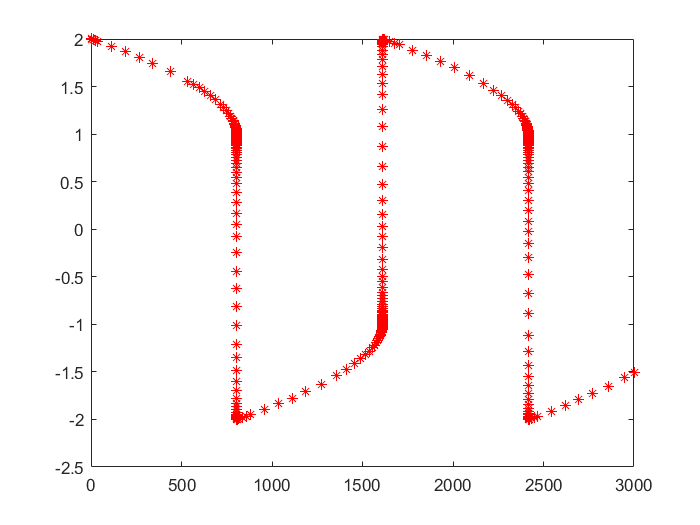

tspan = [0, 3000];
y0 = [2 0];
% [x, y] = ode45(@df1, tspan, y0); % 非常慢，考虑为刚性问题
[x, y] = ode15s(@df1, tspan, y0);n % 很快
plot(x, y(:,1), "r*"); % 作图也可以进一步证明为刚性

## 函数定义

function dy = df1(~, y)
    dy = zeros(2, 1);
    dy(1) = y(2);
    dy(2) = 1000*(1-y(1)^2)*y(2)-y(1);
end